# Chapter 03 — Semantic Topic Map: 

## MiniLM embeddings + 2D layout + representatives

This chapter builds a semantic embedding-based topic map from text (title+abstract).

Purpose

- Produce sentence-transformer embeddings (all-MiniLM-L6-v2) for each work.

- Create a 2D layout for visualization (UMAP preferred; t-SNE fallback).

- Export representative papers per cluster as an inspection aid.

Scope and non-goals

- This chapter is a visualization workflow, not a validated topic model.

- 2D layout (UMAP/t-SNE) is for human inspection only; geometry is not “truth”.

- Cluster IDs are arbitrary labels. Do not treat them as confirmed topics.

- Representatives are “closest to cluster centroid” in embedding space, not “best papers”.

Input contract

- Required: Works JSONL file (pipeline-produced "*.standard.jsonl") OR cfg.input.pipelineJsonl.

- Text is generated by policy = "title+abstract" and cleaned; empty text is dropped.

Dependencies (hard requirements)

- Text Analytics Toolbox

- Add-On: "Text Analytics Toolbox Model for all-MiniLM-L6-v2 Network"

- One of: MATLAB umap() OR FileExchange run_umap OR tsne()

Outputs (written under cfg.runDir)

- Embeddings:                 Ch_03_embeddings.mat

- Embeddings metadata (CSV):  Ch_03_embeddings_meta.csv

- 2D coordinates (CSV):       Ch_03_umap2d.csv  (or Ch_03_tsne2d.csv if fallback)

- Cluster representatives:    Ch_03_cluster_representatives.csv

- Map exports:                Ch_03_map.pdf / Ch_03_map.png

Interpretation guardrails

- Treat this as a reproducible workflow artifact, not an analytical claim.

- Use the exported representatives CSV to inspect what each cluster contains.

--- Code starts below ---

clear; clc;

% Robust repoRoot resolution for Live Script
mlxPath = matlab.desktop.editor.getActiveFilename();
assert(strlength(mlxPath) > 0, "Cannot resolve active file path. Open this .mlx in the Editor and run it.");
examplesDir = fileparts(mlxPath);
repoRoot    = fileparts(examplesDir);
addpath(genpath(fullfile(repoRoot,"src")));
rehash;

% Explicitly provide HubRoot for bootstrap (this repo is the hub)
hubRoot = repoRoot;
setenv("OPENALEX_MATLAB_HUB", hubRoot);

cfg = topicmap.setup("HubRoot", hubRoot);
cfg = topicmap.env_check(cfg);

[topicmap.env_check] WARN (2):
  - Pipeline repo not found (expected <hub>/matlab-openalex-pipeline/src). End-to-end fetch will be unavailable.
  - Normalize repo not found (expected <hub>/matlab-openalex-normalize/src). This is OK for Chapter 02 (JSONL -> Map).
[topicmap.env_check] NEXT (3):
  * Clone matlab-openalex-pipeline under hubRoot and re-run topicmap.env_check().
  * Optional: clone matlab-openalex-normalize only if you want CSV-based workflows.
  * For Chapter 02: set cfg.input.pipelineJsonl to a pipeline output JSONL (works JSONL).


% ---- run output folder ----
cfg.runDir = topicmap.make_run_dir(cfg, "Ch03");

NOTE: Chapter 03 additionally requires the MiniLM-L6-v2 add-on and a 2D layout method (umap/run_umap/tsne).

## 1) choose input JSONL

jsonlPath = "";
if isfield(cfg,"input") && isfield(cfg.input,"pipelineJsonl") && strlength(string(cfg.input.pipelineJsonl))>0
    jsonlPath = string(cfg.input.pipelineJsonl);
end
if strlength(jsonlPath)==0
    d = dir(fullfile(cfg.repoRoot, "data_sample", "*.standard.jsonl"));
    assert(~isempty(d), "No *.standard.jsonl found under data_sample/. Set cfg.input.pipelineJsonl.");
    [~, idxNewest] = max([d.datenum]); % newest sample
    jsonlPath = fullfile(d(idxNewest).folder, d(idxNewest).name);
end
assert(isfile(jsonlPath), "JSONL not found: %s", jsonlPath);
fprintf("Using JSONL: %s\n", jsonlPath);

Using JSONL: D:\workspace\github\matlab-openalex-analyze\data_sample\openalex_MATLAB_cursor_en_1000.standard.jsonl


## 2) load works

W = topicmap.read_pipeline_jsonl(jsonlPath);

## 3) build text (title+abstract)

policy  = "title+abstract";
maxChars = 6000;
if isfield(cfg,"text") && isstruct(cfg.text)
    if isfield(cfg.text,"policy")   && strlength(string(cfg.text.policy))>0
        policy = string(cfg.text.policy);
    end
    if isfield(cfg.text,"maxChars") && ~isempty(cfg.text.maxChars)
        maxChars = cfg.text.maxChars;
    end
end

[text, meta] = topicmap.extract_text(W, policy, maxChars);
text = arrayfun(@topicmap.clean_text, text);

% drop empties
keep = strlength(text) > 0;
text = text(keep);
meta.work_id = meta.work_id(keep);
meta.title   = meta.title(keep);
meta.abstract= meta.abstract(keep);
meta.year    = meta.year(keep);

fprintf("Loaded %d works (non-empty text: %d)\n", numel(W), numel(text));

Loaded 1000 works (non-empty text: 1000)


## 4) Transformer embeddings (MiniLM-L6-v2 via documentEmbedding) 

% Requirement: Add-On "Text Analytics Toolbox Model for all-MiniLM-L6-v2 Network"
% Already checked in env_check, but keep this assert for direct script usage.
okMiniLM = false;
if isfield(cfg,"env") && isstruct(cfg.env)
  if isfield(cfg.env,"optionalOk_Ch03"),    okMiniLM = logical(cfg.env.optionalOk_Ch03); end
  if ~okMiniLM && isfield(cfg.env,"optionalOk_demo03"), okMiniLM = logical(cfg.env.optionalOk_demo03); end
end
assert(okMiniLM, ...
 "Chapter 03 prerequisites not met. Run topicmap.env_check() and install the all-MiniLM-L6-v2 Add-On.");
rng(cfg.seed);
fprintf("Initializing documentEmbedding model: all-MiniLM-L6-v2 ...\n");

Initializing documentEmbedding model: all-MiniLM-L6-v2 ...


emb = documentEmbedding(Model="all-MiniLM-L6-v2");
% Embed in batches to avoid memory spikes (safe default)
batchSize = 128;
if isfield(cfg,"ch03") && isstruct(cfg.ch03) && isfield(cfg.ch03,"batchSize") && ~isempty(cfg.ch03.batchSize)
  batchSize = cfg.ch03.batchSize;
elseif isfield(cfg,"demo03") && isstruct(cfg.demo03) && isfield(cfg.demo03,"batchSize") && ~isempty(cfg.demo03.batchSize)
  batchSize = cfg.demo03.batchSize; % backward compatibility
end
n = numel(text);
E = [];  % will allocate after first batch (dimension depends on model)
fprintf("Embedding %d documents (batchSize=%d)...\n", n, batchSize);

Embedding 1000 documents (batchSize=128)...


tStart = tic;
for i0 = 1:batchSize:n
    i1 = min(n, i0 + batchSize - 1);
    tb = text(i0:i1);

    Eb = embed(emb, tb);  % returns (nb x D)
    if isempty(E)
        % Preallocate as single for disk/memory efficiency
        D = size(Eb, 2);
        E = zeros(n, D, "single");
    end
    E(i0:i1, :) = single(Eb);

    if mod(i0, batchSize*10) == 1 || i1 == n
        fprintf("  embedded %d/%d\n", i1, n);
    end
end

  embedded 128/1000
  embedded 1000/1000


fprintf("Embedding done. Elapsed: %.1fs\n", toc(tStart));

Embedding done. Elapsed: 4.7s


% ---- 4b) save outputs into runDir ----
% Save embeddings + essential metadata
outMat = fullfile(cfg.runDir, "Ch_03_embeddings.mat");
save(outMat, "E", "meta", "jsonlPath", "policy", "maxChars", "batchSize", "-v7.3");
fprintf("Wrote: %s\n", outMat);

Wrote: D:\workspace\github\matlab-openalex-analyze\data_processed\openalex-topicmap\20251224_155735_Ch03\Ch_03_embeddings.mat


% Save meta as CSV for quick inspection / joins
T_meta = table(string(meta.work_id), double(meta.year), string(meta.title), ...
    'VariableNames', {'work_id','year','title'});
outMetaCsv = fullfile(cfg.runDir, "Ch_03_embeddings_meta.csv");
writetable(T_meta, outMetaCsv);
fprintf("Wrote: %s\n", outMetaCsv);

Wrote: D:\workspace\github\matlab-openalex-analyze\data_processed\openalex-topicmap\20251224_155735_Ch03\Ch_03_embeddings_meta.csv


% Optional: lightweight sanity check
fprintf("E size: %d x %d\n", size(E,1), size(E,2));

E size: 1000 x 384


## 5) Dimensionality reduction (PCA -> 2D)

% We reduce embeddings for visualization only.
% Clustering / representatives are based on the original embedding space E.
% Parameters (fixed defaults for reproducibility)
K = 12;       % kmeans clusters (coarse, fixed)
repN = 3;     % representative papers per cluster
pcaDims = 50; % intermediate PCA dims for stable 2D embedding

if isfield(cfg,"ch03") && isstruct(cfg.ch03)
  if isfield(cfg.ch03,"K") && ~isempty(cfg.ch03.K), K = cfg.ch03.K; end
  if isfield(cfg.ch03,"repN") && ~isempty(cfg.ch03.repN), repN = cfg.ch03.repN; end
  if isfield(cfg.ch03,"pcaDims") && ~isempty(cfg.ch03.pcaDims), pcaDims = cfg.ch03.pcaDims; end
elseif isfield(cfg,"demo03") && isstruct(cfg.demo03)
  if isfield(cfg.demo03,"K") && ~isempty(cfg.demo03.K), K = cfg.demo03.K; end
  if isfield(cfg.demo03,"repN") && ~isempty(cfg.demo03.repN), repN = cfg.demo03.repN; end
  if isfield(cfg.demo03,"pcaDims") && ~isempty(cfg.demo03.pcaDims), pcaDims = cfg.demo03.pcaDims; end
end

% PCA
fprintf("Running PCA -> %d dims...\n", pcaDims);

Running PCA -> 50 dims...


[~, Zpca] = pca(double(E), "NumComponents", pcaDims);

## 2D embedding: prefer UMAP if available, otherwise fall back to t-SNE.

Note on pop-up dialogs:

- Some UMAP implementations (especially FileExchange run_umap) may show modal dialogs on first run (e.g., confirmation / dependency notice / cached settings).

- Recommended choice: select "Yes" to proceed, and avoid "Cancel" unless you want to abort the run.

- If you need fully non-interactive execution, prefer MATLAB's built-in umap() when available,or configure run_umap to suppress UI (verbose="none") and avoid GUI access.

If a modal dialog appears (UMAP / run_umap), choose:

- "Yes" to continue (recommended)

-  "Cancel" only to stop and switch to t-SNE fallback

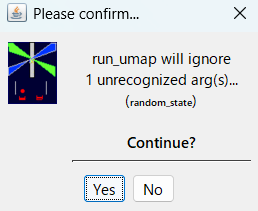

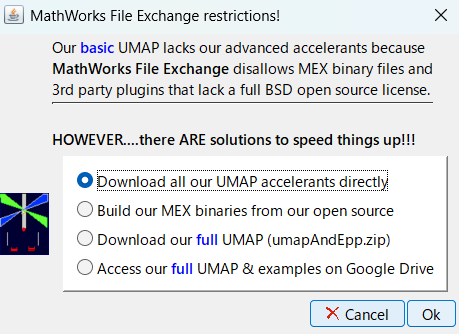

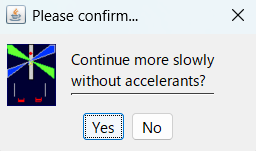

fprintf("Computing 2D embedding...\n");

Computing 2D embedding...


U2 = [];
embedMethod = "";

% R2025b+: Java Swing access to figures is withdrawn, so run_umap must not touch GUI.
% Use 'verbose' = 'none' (or 'text') explicitly to avoid Swing/figure usage.
umapVerbose = "none";
if isfield(cfg,"ch03") && isstruct(cfg.ch03) && isfield(cfg.ch03,"umapVerbose") && strlength(string(cfg.ch03.umapVerbose))>0
  umapVerbose = string(cfg.ch03.umapVerbose);
elseif isfield(cfg,"demo03") && isstruct(cfg.demo03) && isfield(cfg.demo03,"umapVerbose") && strlength(string(cfg.demo03.umapVerbose))>0
  umapVerbose = string(cfg.demo03.umapVerbose);
end

if exist("umap","file") ~= 0
    % Newer MATLAB versions may provide umap()
    try
        % Signature varies across versions; keep it conservative
        U2 = umap(Zpca, "Metric", "cosine", "NumDimensions", 2, "RandomState", cfg.seed);
        embedMethod = "UMAP";
    catch
        U2 = [];
    end
end
if isempty(U2) && exist("run_umap","file") ~= 0
    % File Exchange run_umap
    try
        [U2, ~, ~, ~] = run_umap(Zpca, ...
            "n_components", 2, ...
            "metric", "cosine", ...
            "n_neighbors", 15, ...
            "min_dist", 0.1, ...
            "random_state", cfg.seed, ...
            "verbose", umapVerbose);
        embedMethod = "UMAP(run_umap)";
    catch
        U2 = [];
    end
end

if isempty(U2)
    % Built-in fallback (widely available): t-SNE
    if exist("tsne","file") == 0
        error("No 2D embedding method found. Install/run UMAP (umap or run_umap) or ensure tsne is available.");
    end
    U2 = tsne(Zpca, ...
        "Algorithm", "barneshut", ...
        "Distance", "cosine", ...
        "NumDimensions", 2, ...
        "Standardize", true, ...
        "Perplexity", 30, ...
        "Verbose", 0);
    embedMethod = "t-SNE";
end

fprintf("2D embedding done using %s. U2 size: %d x %d\n", embedMethod, size(U2,1), size(U2,2));

2D embedding done using UMAP(run_umap). U2 size: 1000 x 2


## 6) Clustering (kmeans in embedding-derived 2D for stability)

% Cluster assignment is based on U2 for a simple baseline. (HDBSCAN comes later in demo04.)
fprintf("Clustering with kmeans (K=%d)...\n", K);

Clustering with kmeans (K=12)...


rng(cfg.seed);
idx = kmeans(U2, K, ...
    "Distance", "sqeuclidean", ...
    "Replicates", 10, ...
    "MaxIter", 500, ...
    "Display", "off");

## 7) Representative papers per cluster 

% Representatives are chosen in the ORIGINAL embedding space (not U2).
fprintf("Selecting representatives (repN=%d) in embedding space...\n", repN);

Selecting representatives (repN=3) in embedding space...


Eunit = single(E);
Eunit = Eunit ./ max(vecnorm(Eunit, 2, 2), eps("single")); % normalize rows

repRows = [];
repCluster = [];
repRank = [];
repScore = [];

for c = 1:K
    members = find(idx == c);
    if isempty(members), continue; end
    mu = mean(Eunit(members, :), 1);
    mu = mu ./ max(norm(mu), eps("single"));

    % cosine distance = 1 - cosine similarity
    cosSim = Eunit(members, :) * mu';
    dist = 1 - cosSim;

    [distSorted, ord] = sort(dist, "ascend");
    take = min(repN, numel(ord));
    picked = members(ord(1:take));

    repRows = [repRows; picked(:)];
    repCluster = [repCluster; repmat(c, take, 1)];
    repRank = [repRank; (1:take)'];
    repScore = [repScore; distSorted(1:take)];
end

work_id = string(meta.work_id(repRows)); work_id = work_id(:);
year    = double(meta.year(repRows));    year    = year(:);
paper_title = string(meta.title(repRows)); paper_title = paper_title(:);
cluster = repCluster(:);
rank    = repRank(:);
score   = repScore(:);
x       = U2(repRows,1); x = x(:);
y       = U2(repRows,2); y = y(:);

T_rep = table(cluster, rank, work_id, year, paper_title, score, x, y, ...
    'VariableNames', {'cluster','rank','work_id','year','title','cosine_distance','x','y'});

outRepCsv = fullfile(cfg.runDir, "Ch_03_cluster_representatives.csv");
writetable(T_rep, outRepCsv);
fprintf("Wrote: %s\n", outRepCsv);

Wrote: D:\workspace\github\matlab-openalex-analyze\data_processed\openalex-topicmap\20251224_155735_Ch03\Ch_03_cluster_representatives.csv


% Save 2D coords + cluster assignment (normalize shapes + use legacy VariableNames syntax)
work_id_all = string(meta.work_id); work_id_all = work_id_all(:);
year_all    = double(meta.year);    year_all    = year_all(:);
x_all       = U2(:,1);              x_all       = x_all(:);
y_all       = U2(:,2);              y_all       = y_all(:);
cluster_all = idx;                  cluster_all = cluster_all(:);

% defensive assert
H2 = [numel(work_id_all) numel(year_all) numel(x_all) numel(y_all) numel(cluster_all)];
assert(all(H2==H2(1)), "U2 table column height mismatch: %s", mat2str(H2));

T_u2 = table(work_id_all, year_all, x_all, y_all, cluster_all, ...
    'VariableNames', {'work_id','year','x','y','cluster'});
outU2Csv = fullfile(cfg.runDir, "Ch_03_umap2d.csv");
writetable(T_u2, outU2Csv);
fprintf("Wrote: %s\n", outU2Csv);

Wrote: D:\workspace\github\matlab-openalex-analyze\data_processed\openalex-topicmap\20251224_155735_Ch03\Ch_03_umap2d.csv


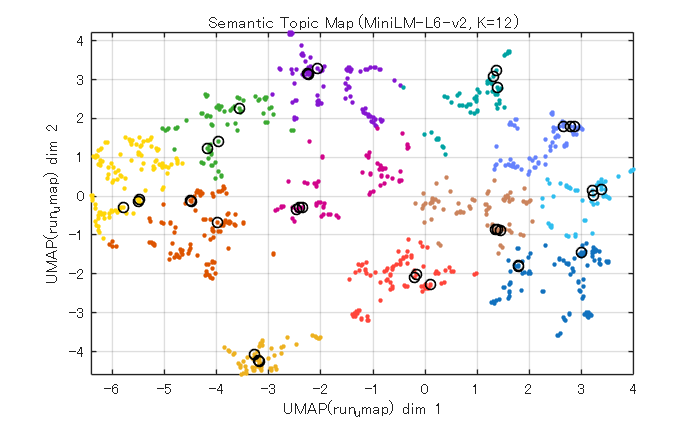

%% Figure (academic-ish)
f = figure("Name","Ch_03 Semantic Topic Map", "Color","w");
ax = axes(f);
hold(ax, "on");

% plot all points
gscatter(ax, U2(:,1), U2(:,2), idx, [], ".", 8, "off");
grid(ax, "on");
box(ax, "on");
axis(ax, "tight");
ax.XLabel.String = sprintf("%s dim 1", embedMethod);
ax.YLabel.String = sprintf("%s dim 2", embedMethod);
ax.Title.String  = sprintf("Semantic Topic Map (MiniLM-L6-v2, K=%d)", K);

% highlight representatives
plot(ax, T_rep.x, T_rep.y, "ko", "MarkerSize", 6, "LineWidth", 1);

% export
outPdf = fullfile(cfg.runDir, "Ch_03_map.pdf");
outPng = fullfile(cfg.runDir, "Ch_03_map.png");
exportgraphics(f, outPdf, "ContentType","vector");
exportgraphics(f, outPng, "Resolution", 300);

fprintf("Wrote: %s\nWrote: %s\n", outPdf, outPng);

Wrote: D:\workspace\github\matlab-openalex-analyze\data_processed\openalex-topicmap\20251224_155735_Ch03\Ch_03_map.pdf
Wrote: D:\workspace\github\matlab-openalex-analyze\data_processed\openalex-topicmap\20251224_155735_Ch03\Ch_03_map.png


fprintf("Ch_03 Step5-7 complete.\n");

Ch_03 Step5-7 complete.
